# Analyze heat capacity from DR

This routine is intended at fitting Cp data on Y-substituted TmVO4 acquired with our DR used in the Dynacool PPMS of the Lee lab

## Average data

Import data and compute average of data points taken at same setpoint temperature

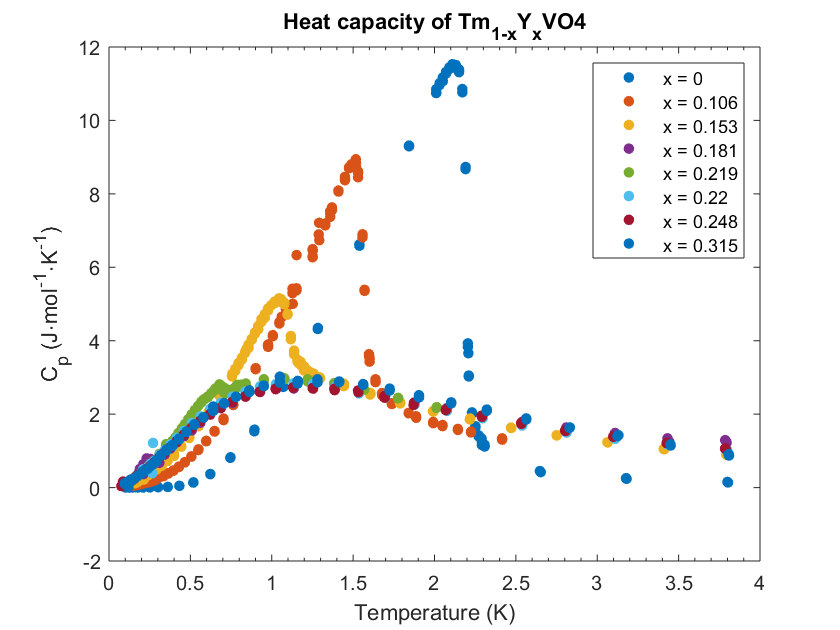

Structure containing averaged data is called avgData


YTmVO4_primary_analysis;

% run script that imports and computes the average of Cp data of all
% desired compositions

### Plot averaged data

#### Plot averaged Cp data for YTmVO4 x<xc

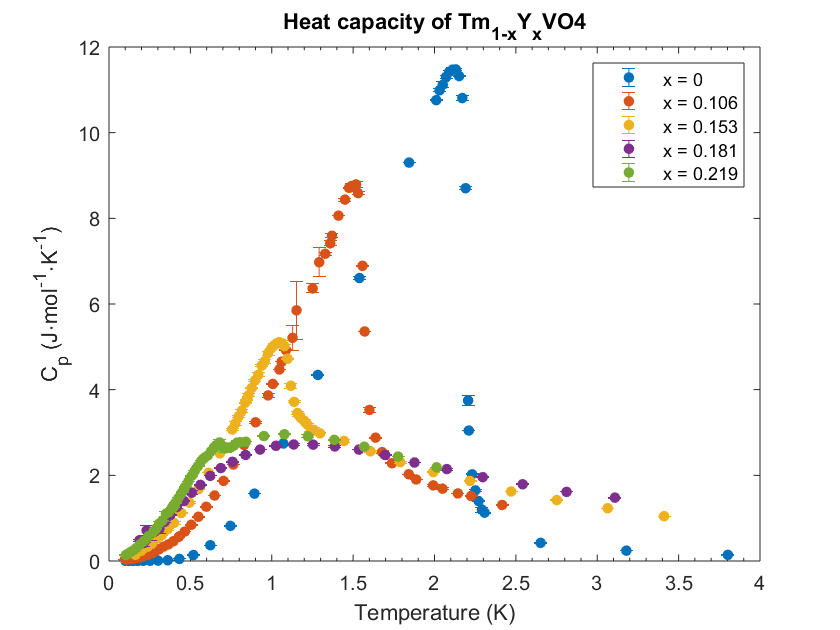

Lord = L-3;% index of the last dataset with Cp jump
plotAvgCp(avgData,dpg,1,Lord)
title(ttlCpY)

#### Plot averaged data for x>xc

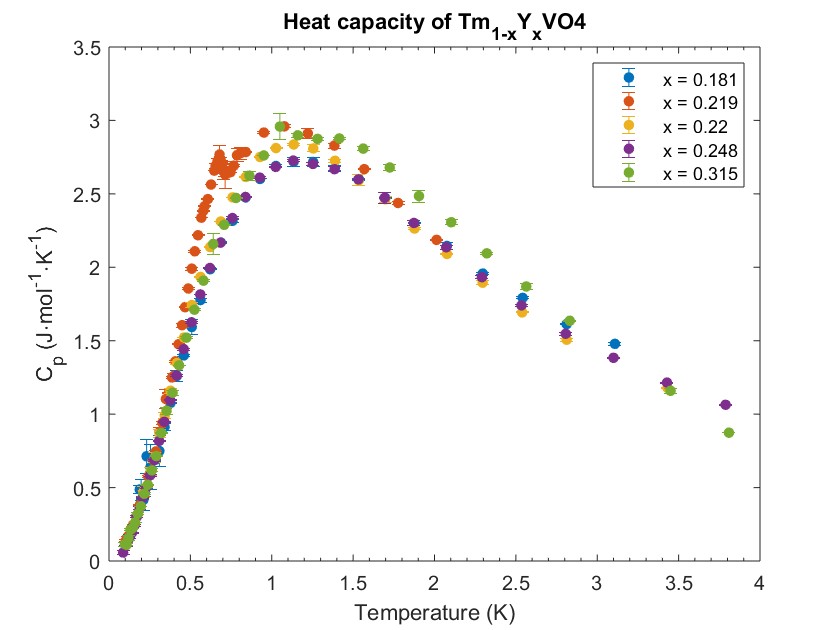

plotAvgCp(avgData,dpg,Lord-1,L)
title(ttlCpY)

## Fit data

### Fit parameters

Tmfmax = [2.1,1.4,0.9,0.2,0.68];% Maximum temperature of mean-field jump for x=0 to x=0.219
% This is a visual estimate of the temperature below which Cp shows a mean-field jump. It only applies for x<xc.
Tc = [2.2,1.57,1.11,0.24,0.69];% Transition temperature
Tschmin = [2.3,1.7,1.2,0.25,0.7];% temperature above which the data are essentially Schottky-like
x0 = [1e-7 0.5];% range of the pseudospin

### Fit mean-field jump for pure TmVO4

    'Coeffsnorm names'    'Amf'



    8.3047



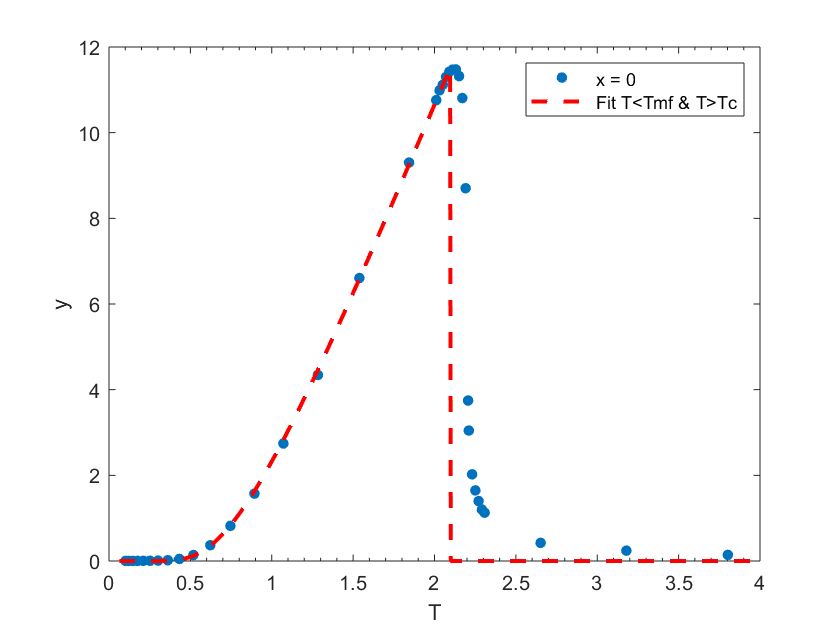

for i=1
    ftmf = fittype(@(Amf,T) fitCpmf(T,Tc(i),Tmfmax(i),Amf),'independent', 'T', 'dependent', 'y' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.StartPoint = [1];% Amf,An,mu,sgm in this order
    opts.Lower = [0];
%     opts.Upper = [Inf Inf 5 5 ];

% Fit mean-field heat capacity jump to data below Tmfmin
    disp(['Coeffsnorm names',coeffnames(ftmf)'])
    [avgData(i).fitmf, avgData(i).ffgof] = fit(avgData(i).T',avgData(i).Cp',ftmf,opts);
    disp(coeffvalues(avgData(i).fitmf))
    figure( 'Name', 'Schottky anomaly' );
    p0 = plot(avgData(i).T', avgData(i).Cp','.' , 'markers',18);%,'DisplayName','x = 0.32');
    hold on
    p2 = plot(avgData(i).fitmf,'--r');%,'DisplayName','Normal');
    legend({['x = ',num2str(dpg(i))],'Fit T<Tmf & T>Tc'})
end

### Extrapolate fit below Tmfmax up to Tc

G = [0.01:0.01:0.48,0.5-logspace(-2,-15,50)];% range of pseudospin
Tfit = ones(length(Tc),length(G));
for ii=1:2
    avgData(i).fp = @(x) (fmf(x,avgData(i).fitmf.Amf));% Mean-field fitting function below Tmfmin
    Tfit(ii,:) = Tc(ii)*2*G./atanh(2*G);% temperature interval corresponding to the full pseudospin interval
%     fplot(avgData(i).fp,x0);% plot the function on its full interval for each doping level
%     plot(Tfit(ii,:),f(G))% plot Cp fit function on the temperature interval for each doping
end

#### Plot data and extrapolated fit as a function of temperature

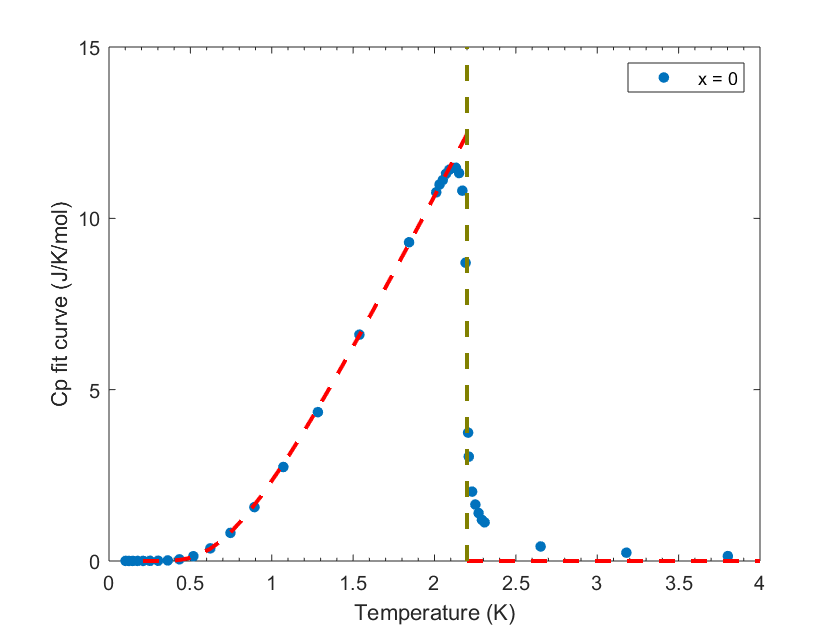

for ii=1
    figure 
    plot(avgData(ii).T,avgData(ii).Cp,'.')
    hold on
    plot(Tfit(ii,:),avgData(ii).fp(G),'--r');%,'DisplayName',['x = ',num2str(dpg(ii))])
    line([Tc(ii),max(xlim)],[0,0],'Color','red','LineStyle','--')
    line([Tc(ii),Tc(ii)],ylim,'Color',[0.5 0.5 0],'LineStyle','--')
    xlabel('Temperature (K)')
    ylabel('Cp fit curve (J/K/mol)')
    legend(['x = ',num2str(dpg(ii))])
hold off
end

## Fit data for x>0

### Compute average gap delta0 from transition temperature

See Gehring1976a equation 5.

delta = function_handle with value:
    @(x)(1-dpg(i))*4*Tc(1)/sqrt(pi)*integral(@(u)exp(-u^2)/cosh(x*u/Tc(i)),-inf,inf,'ArrayValued',true)-Tc(i)


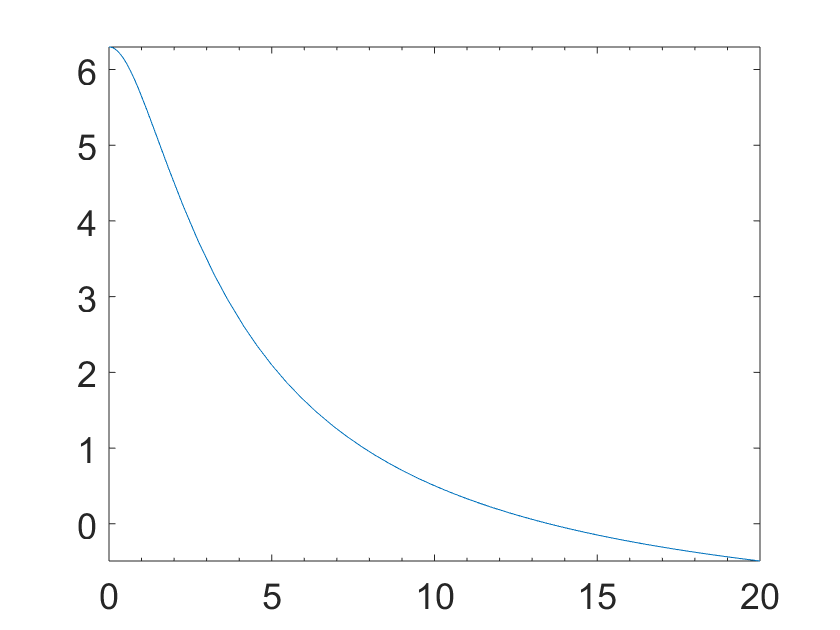

delta0 =     1.0000   13.5141    1.0000    1.0000    1.0000


delta0 = ones(size(Tc));
for i=2
    delta = @(x) (1-dpg(i))*4*Tc(1)/sqrt(pi)*integral(@(u)exp(-u^2)/cosh(x*u/Tc(i)),-inf,inf,'ArrayValued',true)-Tc(i)
    fplot(delta,[0 20])
    delta0(i) = fzero(@(x)delta(x),[0 100])
end

### Compute the pseudospin as a function of temperature

See Gehring1976a equation 4

sigma = function_handle with value:
    @(x,T)1/sqrt(pi)*integral(@(u)exp(-u^2)*tanh((delta0(i)*u+4*Tc(1)*x)./T),-inf,inf,'ArrayValued',true)-x


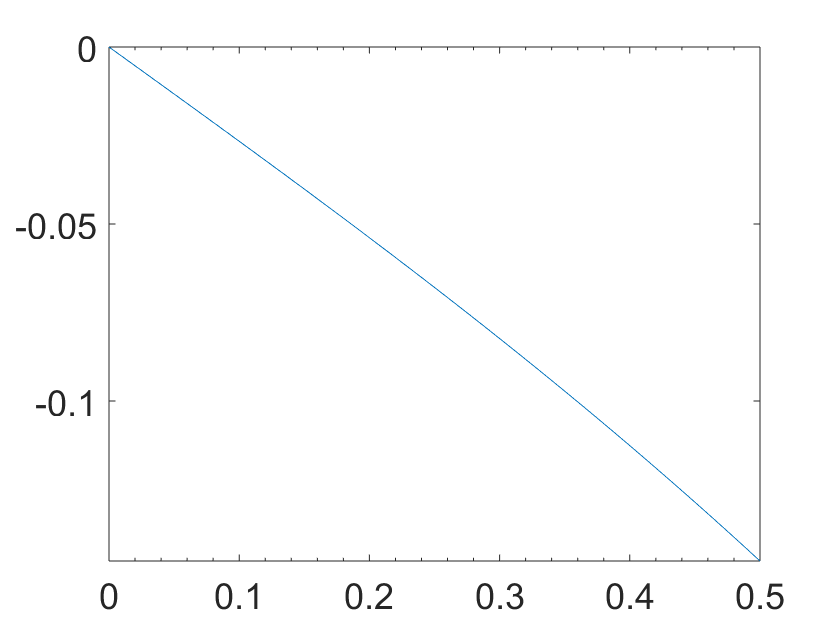

for i=2
    sigma = @(x,T) 1/sqrt(pi)*integral(@(u)exp(-u^2)*tanh((delta0(i)*u+4*Tc(1)*x)./T),-inf,inf,'ArrayValued',true)-x
    fplot(@(x)sigma(x,0.1),[0 0.5])
end

Need to check: delta0(i) should be of the same OM as Tc(i)